{Corrections below}

s =   SettingsGroup with properties:

                slhistory: [1×1 SettingsGroup]
                 Simulink: [1×1 SettingsGroup]
    mldrivetripwireaccess: [1×1 SettingsGroup]
                   matlab: [1×1 SettingsGroup]


% 1.7a) angle nearest neighbour is articles 9 and 10
% 1.7b) angle nearest neighbour is articles 9 and 10
% 1.7d) the TF-IDF adds a weight component to make sure commonely used
% words between articles such as "the" are weighed less than more rarer and
% important key words per article.
% 1.8c) wrong graphs not sure why

#### **Problem 1.7 a) **

B = transpose(V)

B =      0     0     1     0     0     0     0     0     1     0     0     1     1     0     1     0     0     0     0     0     0     2     0     1     1     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0
     0     0     0     4     2     0     0     0     0     2     1     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     1     0     1     0     0     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     2
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0   

dist = pdist(B)

dist =    32.2955   35.8050   44.3959   32.2025   55.2540   29.0000   31.0805   48.1560   40.3485   34.7707   42.1426   35.3553   53.3292   33.1361   34.9428   45.9347   39.7366   46.6154   33.6601   56.4535   37.2961   37.9737   45.2217   40.1497   50.2792   51.3809   46.3681   50.1498   51.7301   48.0729   59.7662   29.0517   30.9031   48.5592   41.9881   57.6541   62.5700   50.5569   51.9326   24.7184   50.5371   42.2493   53.3573   43.2435   34.3948


square = squareform(dist)

square =          0   32.2955   35.8050   44.3959   32.2025   55.2540   29.0000   31.0805   48.1560   40.3485
   32.2955         0   34.7707   42.1426   35.3553   53.3292   33.1361   34.9428   45.9347   39.7366
   35.8050   34.7707         0   46.6154   33.6601   56.4535   37.2961   37.9737   45.2217   40.1497
   44.3959   42.1426   46.6154         0   50.2792   51.3809   46.3681   50.1498   51.7301   48.0729
   32.2025   35.3553   33.6601   50.2792         0   59.7662   29.0517   30.9031   48.5592   41.9881
   55.2540   53.3292   56.4535   51.3809   59.7662         0   57.6541   62.5700   50.5569   51.9326
   29.0000   33.1361   37.2961   46.3681   29.0517   57.6541         0   24.7184   50.5371   42.2493
   31.0805   34.9428   37.9737   50.1498   30.9031   62.5700   24.7184         0   53.3573   43.2435
   48.1560   45.9347   45.2217   51.7301   48.5592   50.5569   50.5371   53.3573         0   34.3948
   40.3485   39.7366   40.1497   48.0729   41.9881   51.9326   42.2493   43.2435  

min_dist = min(dist(dist>0))

min_dist = 24.7184

% articles 7 and 8 are nearest neighbours

angle = -1 * (pdist(B, "cosine")) + 1

angle =     0.7124    0.6694    0.6669    0.6345    0.7144    0.6863    0.6190    0.7154    0.7328    0.7136    0.7082    0.6330    0.7260    0.6726    0.6250    0.7388    0.7398    0.6402    0.6997    0.6721    0.6107    0.5889    0.7461    0.7356    0.5394    0.7385    0.6378    0.5483    0.6765    0.6715    0.6432    0.6275    0.5376    0.7257    0.7118    0.7215    0.6322    0.7585    0.7318    0.6506    0.7096    0.7247    0.6745    0.7353    0.8614


sq_angle = squareform(angle)

sq_angle =          0    0.7124    0.6694    0.6669    0.6345    0.7144    0.6863    0.6190    0.7154    0.7328
    0.7124         0    0.7136    0.7082    0.6330    0.7260    0.6726    0.6250    0.7388    0.7398
    0.6694    0.7136         0    0.6402    0.6997    0.6721    0.6107    0.5889    0.7461    0.7356
    0.6669    0.7082    0.6402         0    0.5394    0.7385    0.6378    0.5483    0.6765    0.6715
    0.6345    0.6330    0.6997    0.5394         0    0.6432    0.6275    0.5376    0.7257    0.7118
    0.7144    0.7260    0.6721    0.7385    0.6432         0    0.7215    0.6322    0.7585    0.7318
    0.6863    0.6726    0.6107    0.6378    0.6275    0.7215         0    0.6506    0.7096    0.7247
    0.6190    0.6250    0.5889    0.5483    0.5376    0.6322    0.6506         0    0.6745    0.7353
    0.7154    0.7388    0.7461    0.6765    0.7257    0.7585    0.7096    0.6745         0    0.8614
    0.7328    0.7398    0.7356    0.6715    0.7118    0.7318    0.7247    0.7353

min_angle = min(angle(angle>0))

min_angle = 0.5376

% articles 5 and 8 are nearest angle neighbours

% Distance and angle are geometrically different in this case as distance
% would be a measure of how many times all words are used in an article, and this 
% would be compared to other articles. Angle would be measuring how 
% many unique words are shared between the two articles. 
% This would, more often than not, produce a differing pair.


**Problem 1.7 b)**

C = transpose(normalize(V))

C =    -0.2339   -0.2339    0.8240   -0.2339   -0.2339   -0.2339   -0.2339   -0.2339    0.8240   -0.2339   -0.2339    0.8240    0.8240   -0.2339    0.8240   -0.2339   -0.2339   -0.2339   -0.2339   -0.2339   -0.2339    1.8819   -0.2339    0.8240    0.8240   -0.2339   -0.2339   -0.2339   -0.2339    0.8240   -0.2339   -0.2339   -0.2339   -0.2339   -0.2339   -0.2339   -0.2339   -0.2339   -0.2339   -0.2339    1.8819   -0.2339   -0.2339   -0.2339   -0.2339   -0.2339   -0.2339   -0.2339   -0.2339   -0.2339
   -0.2172   -0.2172   -0.2172    3.4989    1.6408   -0.2172   -0.2172   -0.2172   -0.2172    1.6408    0.7118   -0.2172   -0.2172   -0.2172   -0.2172   -0.2172   -0.2172   -0.2172   -0.2172   -0.2172   -0.2172   -0.2172    0.7118   -0.2172   -0.2172   -0.2172   -0.2172   -0.2172   -0.2172   -0.2172   -0.2172   -0.2172   -0.2172    0.7118   -0.2172    0.7118   -0.2172   -0.2172   -0.2172   -0.2172   -0.2172   -0.2172   -0.2172   -0.2172   -0.2172    0.7118   -0.2172   -0.2172   -0.2172   -0

dist_2 = pdist(C)

dist_2 =    31.5742   33.7582   34.1055   35.4254   31.4505   32.8308   36.2253   31.3352   30.4242   31.3818   31.8451   35.4647   30.7589   33.5163   35.8981   29.9872   29.9828   35.2500   32.0346   33.5684   36.4903   37.5182   29.5101   30.1492   39.8188   30.1208   35.3156   39.4907   33.4423   33.7804   34.9590   35.6540   39.7405   30.6223   31.4195   30.8997   35.5375   28.8223   30.4247   34.5613   31.5287   30.7265   33.3979   30.1503   21.8341


square_2 = squareform(dist_2)

square_2 =          0   31.5742   33.7582   34.1055   35.4254   31.4505   32.8308   36.2253   31.3352   30.4242
   31.5742         0   31.3818   31.8451   35.4647   30.7589   33.5163   35.8981   29.9872   29.9828
   33.7582   31.3818         0   35.2500   32.0346   33.5684   36.4903   37.5182   29.5101   30.1492
   34.1055   31.8451   35.2500         0   39.8188   30.1208   35.3156   39.4907   33.4423   33.7804
   35.4254   35.4647   32.0346   39.8188         0   34.9590   35.6540   39.7405   30.6223   31.4195
   31.4505   30.7589   33.5684   30.1208   34.9590         0   30.8997   35.5375   28.8223   30.4247
   32.8308   33.5163   36.4903   35.3156   35.6540   30.8997         0   34.5613   31.5287   30.7265
   36.2253   35.8981   37.5182   39.4907   39.7405   35.5375   34.5613         0   33.3979   30.1503
   31.3352   29.9872   29.5101   33.4423   30.6223   28.8223   31.5287   33.3979         0   21.8341
   30.4242   29.9828   30.1492   33.7804   31.4195   30.4247   30.7265   30.1503

min_dist_2 = min(dist_2(dist_2>0))

min_dist_2 = 21.8341

% Articles 9 and 10 are nearest neighbours

angle_2 = -1 * (pdist(C, "cosine")) + 1

angle_2 =     0.6979    0.6547    0.6475    0.6197    0.7003    0.6734    0.6023    0.7025    0.7195    0.7016    0.6927    0.6189    0.7133    0.6596    0.6095    0.7275    0.7276    0.6235    0.6890    0.6585    0.5965    0.5734    0.7361    0.7246    0.5195    0.7251    0.6221    0.5274    0.6611    0.6542    0.6297    0.6148    0.5214    0.7158    0.7009    0.7107    0.6173    0.7483    0.7195    0.6380    0.6988    0.7139    0.6620    0.7245    0.8555


sq_angle_2 = squareform(angle_2)

sq_angle_2 =          0    0.6979    0.6547    0.6475    0.6197    0.7003    0.6734    0.6023    0.7025    0.7195
    0.6979         0    0.7016    0.6927    0.6189    0.7133    0.6596    0.6095    0.7275    0.7276
    0.6547    0.7016         0    0.6235    0.6890    0.6585    0.5965    0.5734    0.7361    0.7246
    0.6475    0.6927    0.6235         0    0.5195    0.7251    0.6221    0.5274    0.6611    0.6542
    0.6197    0.6189    0.6890    0.5195         0    0.6297    0.6148    0.5214    0.7158    0.7009
    0.7003    0.7133    0.6585    0.7251    0.6297         0    0.7107    0.6173    0.7483    0.7195
    0.6734    0.6596    0.5965    0.6221    0.6148    0.7107         0    0.6380    0.6988    0.7139
    0.6023    0.6095    0.5734    0.5274    0.5214    0.6173    0.6380         0    0.6620    0.7245
    0.7025    0.7275    0.7361    0.6611    0.7158    0.7483    0.6988    0.6620         0    0.8555
    0.7195    0.7276    0.7246    0.6542    0.7009    0.7195    0.7139    0.72

min_angle_2 = min(angle_2(angle_2>0))

min_angle_2 = 0.5195

% Articles 5 and 4 are angle nearest neighbours

% The angle nearest neighbour and nearest neighbour has changed now. 
% Normalizing the data would provide a more accurate result in likeliness
% between articles, which provides a greater incentive to utilize
% normalized data in similar caluclations.

**Problem 1.7 c)**

% c)
W = zeros(1651, 10)

W =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


for i = 1:10
    for o = 1:1651
        II = nnz(V(o,:));
        W(o, i) = sqrt(log(10/II)) * V(o, i)/sum(V(:, i));
    end
end
W_T = transpose(W)

W_T =          0         0    0.0042         0         0         0         0         0    0.0042         0         0    0.0042    0.0042         0    0.0035         0         0         0         0         0         0    0.0083         0    0.0042    0.0035         0         0         0         0    0.0042         0         0         0         0         0         0         0         0         0         0    0.0070         0         0         0         0         0         0         0         0         0
         0         0         0    0.0131    0.0057         0         0         0         0    0.0079    0.0039         0         0         0         0         0         0         0         0         0         0         0    0.0039         0         0         0         0         0         0         0         0         0         0    0.0033         0    0.0033         0         0         0         0         0         0         0         0         0    0.0039         0         0         0   

dist_W = pdist(W_T)

dist_W =     0.1075    0.1169    0.1043    0.1176    0.0978    0.1131    0.1210    0.0990    0.0968    0.1201    0.1039    0.1251    0.1050    0.1207    0.1254    0.1071    0.1051    0.1148    0.1312    0.1167    0.1265    0.1327    0.1143    0.1130    0.1217    0.0983    0.1166    0.1246    0.1027    0.1016    0.1167    0.1246    0.1344    0.1122    0.1118    0.1100    0.1201    0.0972    0.0960    0.1303    0.1097    0.1073    0.1136    0.0965    0.0821


square_W = squareform(dist_W)

square_W =          0    0.1075    0.1169    0.1043    0.1176    0.0978    0.1131    0.1210    0.0990    0.0968
    0.1075         0    0.1201    0.1039    0.1251    0.1050    0.1207    0.1254    0.1071    0.1051
    0.1169    0.1201         0    0.1148    0.1312    0.1167    0.1265    0.1327    0.1143    0.1130
    0.1043    0.1039    0.1148         0    0.1217    0.0983    0.1166    0.1246    0.1027    0.1016
    0.1176    0.1251    0.1312    0.1217         0    0.1167    0.1246    0.1344    0.1122    0.1118
    0.0978    0.1050    0.1167    0.0983    0.1167         0    0.1100    0.1201    0.0972    0.0960
    0.1131    0.1207    0.1265    0.1166    0.1246    0.1100         0    0.1303    0.1097    0.1073
    0.1210    0.1254    0.1327    0.1246    0.1344    0.1201    0.1303         0    0.1136    0.0965
    0.0990    0.1071    0.1143    0.1027    0.1122    0.0972    0.1097    0.1136         0    0.0821
    0.0968    0.1051    0.1130    0.1016    0.1118    0.0960    0.1073    0.0965

min_dist_W = min(dist_W(dist_W>0))

min_dist_W = 0.0821

% Articles 9 and 10 are closest by euclidean distance 

**Problem 1.7 d)**

The TF-IDF is an even more precise way to compare and contrast articles by their likeliness. What is it doing is taking the normalization, and scaling it by a factor of sqrt(log(of how many times the word shows up across all the documents)^-1)). This scaling is just another measure of how close each article is to each other and increases the accuracy of the computations and result.

**Problem 1.8 a)**

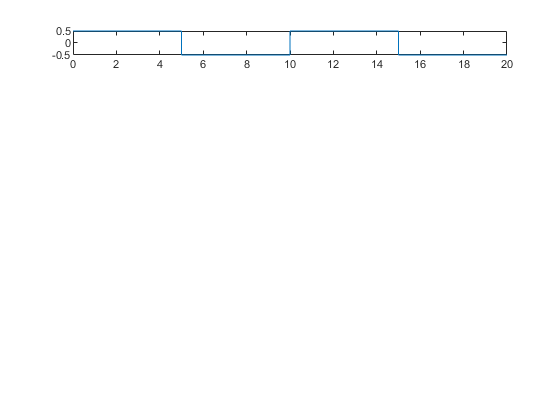

[time_pos, sq_wave, B_unnorm] = generate_data;

% sq_wave vs time_pos
subplot(8, 1, 1);
plot(time_pos, sq_wave)

**Problem 1.8 b)**

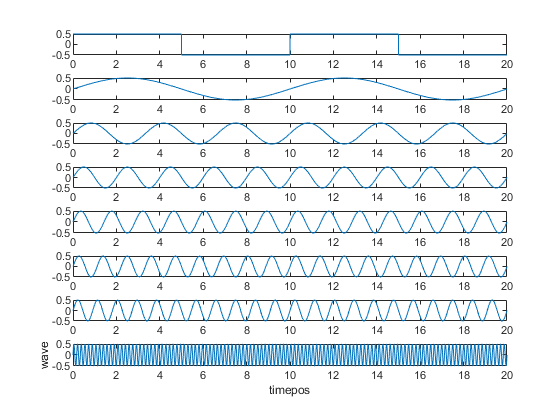

% How would you numerically test for the orthogonality of the basis vectors (rows of B unnorm)?
% To test for orthogonality, you can calculate the dot product between each
% basis vector and sum up the resulting number, which should return 0 if
% they are all orthogonal to each other

% first 6 vectors of B_unnorm
for i = 2:7
    subplot(8, 1, i);
    plot(time_pos, B_unnorm(i - 1,:))
end

% 30th vector of B_unnorm
subplot(8, 1, 8);
plot(time_pos, B_unnorm(30,:))

ylabel("wave")
xlabel("timepos")

**Problem 1.8 c)**

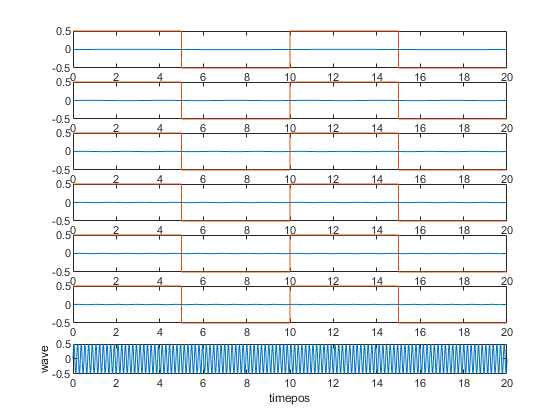

norm_num = norm(B_unnorm);
B_norm = B_unnorm/norm_num; % normalizing
proj = zeros(30, 1); % coefficients
for i = 1:30
    proj(i, 1) = sq_wave * B_norm(i, :)'; % caluclating proj
end
temp = [proj, B_norm];
B_sort = sortrows(temp, "descend");
B_sort(:, 1) = [];

for i = 1:6
    subplot(7, 1, i);
    plot(time_pos, B_sort(i,:), time_pos, sq_wave);
end

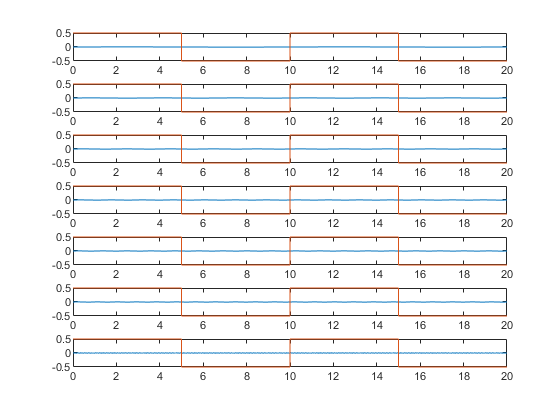


subplot(7, 1, 7);
plot(time_pos, B_sort(30,:), time_pos, sq_wave);


% Something is clearly off as the approximation is nowhere near close to
% what the sq_wave is, I'm not sure why though.


s.matlab.colors.CommentColor.TemporaryValue = [255, 0, 0]

s =   SettingsGroup with properties:

                slhistory: [1×1 SettingsGroup]
                 Simulink: [1×1 SettingsGroup]
    mldrivetripwireaccess: [1×1 SettingsGroup]
                   matlab: [1×1 SettingsGroup]


% 1.7a) articles 10 and 9 are angle nearest neighbours
%    b) articles 10 and 9 are angle nearest neighbours
%    d) TF-IDF is weighs how common certain words are across articles and
%    uses that to compare articles.
